# EFMouse: 1 x 1 with craniotomy (csf-csf) montage

EFMouse is a Matlab tool for electric field modelling in the mouse brain.

This notebook reproduces results for the 1 x 1 with craniotomy (csf-csf) montage in: 

Sanchez-Romero R., Akyuz, S., & Krekelberg, B. (2024). EFMouse: a Matlab toolbox to model electric fields in the mouse brain. bioRxiv. https://doi.org/10.1101/2024.07.25.605227

The notebook is also an introductory tutorial to simulate other montages.

*(Developed by Ruben Sanchez-Romero and Bart Krekelberg,*

*Rutgers-Newark, Center for Molecular and Behavioral Neuroscience,*

*for support open an issue in https://github.com/klabhub/EFMouse/issues)*

## Introduction

EFMouse combines several elements from previous work: 

- Anatomical data from the Digimouse project.

- A refined finite element mesh of the Digimouse by Alekseichuk et al., (2019), *Neuroimage*. 

- Matlab code and inspiration from the ROAST toolbox.

- The getDP finite element method (FEM) solver (v 3.2.0).

- The Allen mouse brain atlas.

Key new functionality includes: 

- Positioning electrodes in arbitrary locations in and on the mouse body.

- Modeling craniotomies in the mouse skull.

- Analyzing the electric field in user-defined regions of interest

- Analyzing the electric field in brain regions defined in the Allen mouse atlas.

- A measure of relative focality of the electric field.

- A measure of direction homogeneity of the electric field.

For details see Sanchez-Romero et al., (2024) and *EFMouse.m* Matlab code.

## Typical workflow

The typical workflow to generate a model consists of several stages

- Stage.INIT           : Initialize. 

- Stage.MESH       : Define elecrodes and (optionally) a craniotomy.

- Stage.EXPORT   : Export files for the FEM solver getDP.

- Stage.GETDP     : Run the FEM solver.

- Stage.ATLAS      : Map the results to the Allen mouse atlas.

### Stage INIT: Initialize

We start by setting up the basic parameters of the `EFMouse` object:

o = EFMouse; % Create a default empty object of the class EFMouse
o.ID = '1x1_cran_csf_csf';  % A name/tag for this simulation.
o.dir = '/Users/rubensanchez/desktop/efmouse_sim/1x1_cran_csf_csf'; % Results and the object (1x1_cran.mat) will be saved here.
o.log  = true;  % Create a log file.

Note: The log file is created but doesn't update when running a simulation from a notebook (like here). It will properly update when running EFMouse directly from the Matlab command line.

`initialize()` creates the folder to store the results. With `overwrite=true`, anything in this folder will be deleted.

o.initialize(overwrite=true); 

The initialized `EFMouse` object contains the default mouse mesh (without stimulation electrodes). Let's visualize the brain tissue. You can select different tissues to visualize.

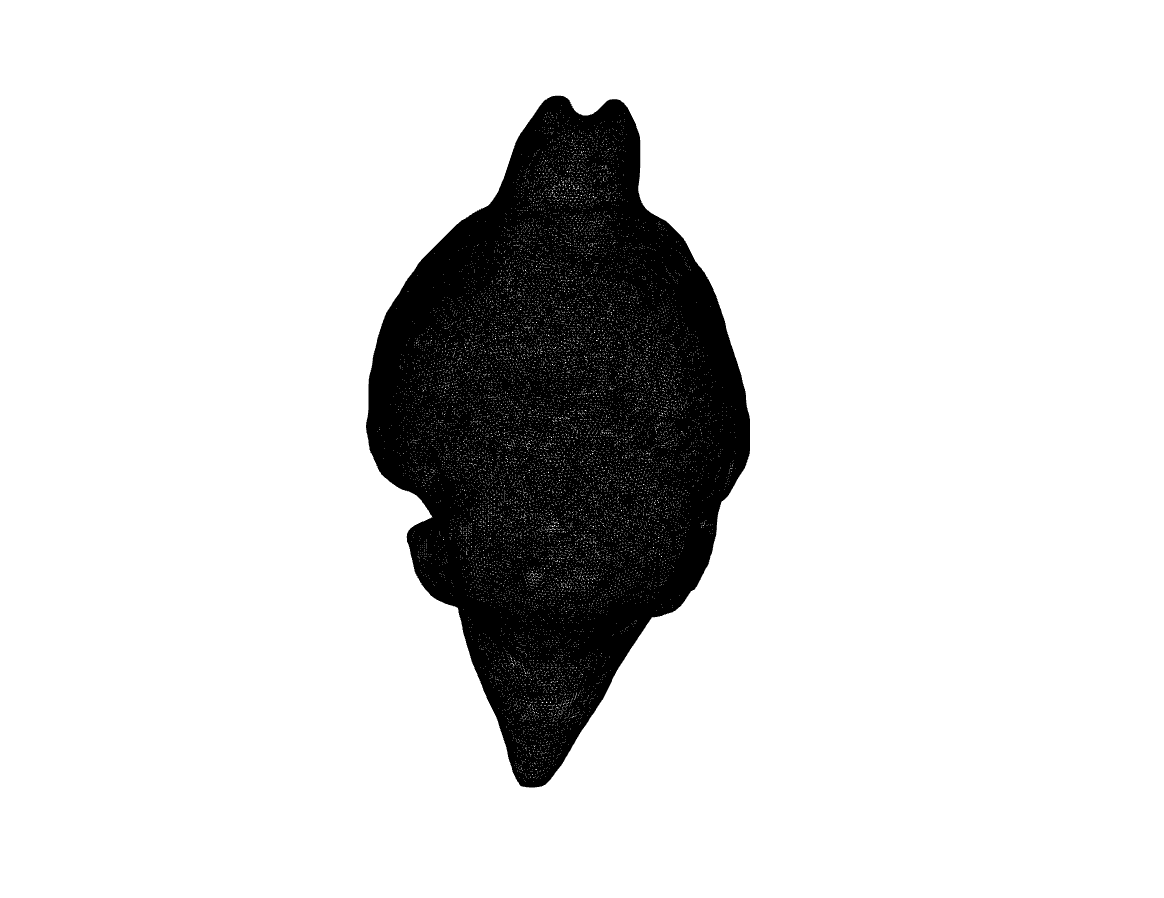

plotMesh(o,tissue='gray')

The mesh is pretty dense, so it may look like a black blob. The olfactory bulbs are visible on the top. In a regular figure window, you can use the Matlab figure tools to rotate or zoom. (You can also adapt the `plotMesh()` function in *EFMouse.m* to modifiy the figure directly.)

### Stage MESH: Create electrodes and a craniotomy

Now we define a 1x1 stimulation montage, targeting visual areas.  The surface type is an electrode that is placed on top of the animal (simulating how gel would be placed on the skin).

o.addElectrode(tag = "Anterior",current = 0.2,type="surface",shape="circle",center= [-3.5,30,6],radius=0.6, thickness=1);
o.addElectrode(tag = "Posterior",current = -0.2,type="surface",shape="circle",center= [-3.5,25,6],radius=0.6, thickness=1);

Add a craniotomy between the stimulation electrodes. Select the material replacing the space where skin and bone were removed. Here, we simulate csf flowing into the space of removed bone and skin.   

o.addCraniotomy(tag = "left",center=[-3.5,27.5,6],radius=1.5,material=["csf","csf"]);

To update the model with the electrodes and the craniotomy, we run the pipeline to Stage.MESH. With `show=true`, this also opens a figure for inspection of the mesh:

Compute stage MESH
EF Mouse Model (label: 1x1_cran_csf_csf) in directory /Users/rubensanchez/desktop/efmouse_sim/1x1_cran_csf_csf (stage=INIT).
-Meshing 2 electrodes-
Closest skin node is 0.7 away from the Anterior electrode target position.
Closest skin node is 0.1 away from the Posterior electrode target position.
Found  tet #2891752 at a distance of 0.46 from the target (label : skin)
Replacing skin with csf 
Replacing bone with csf 


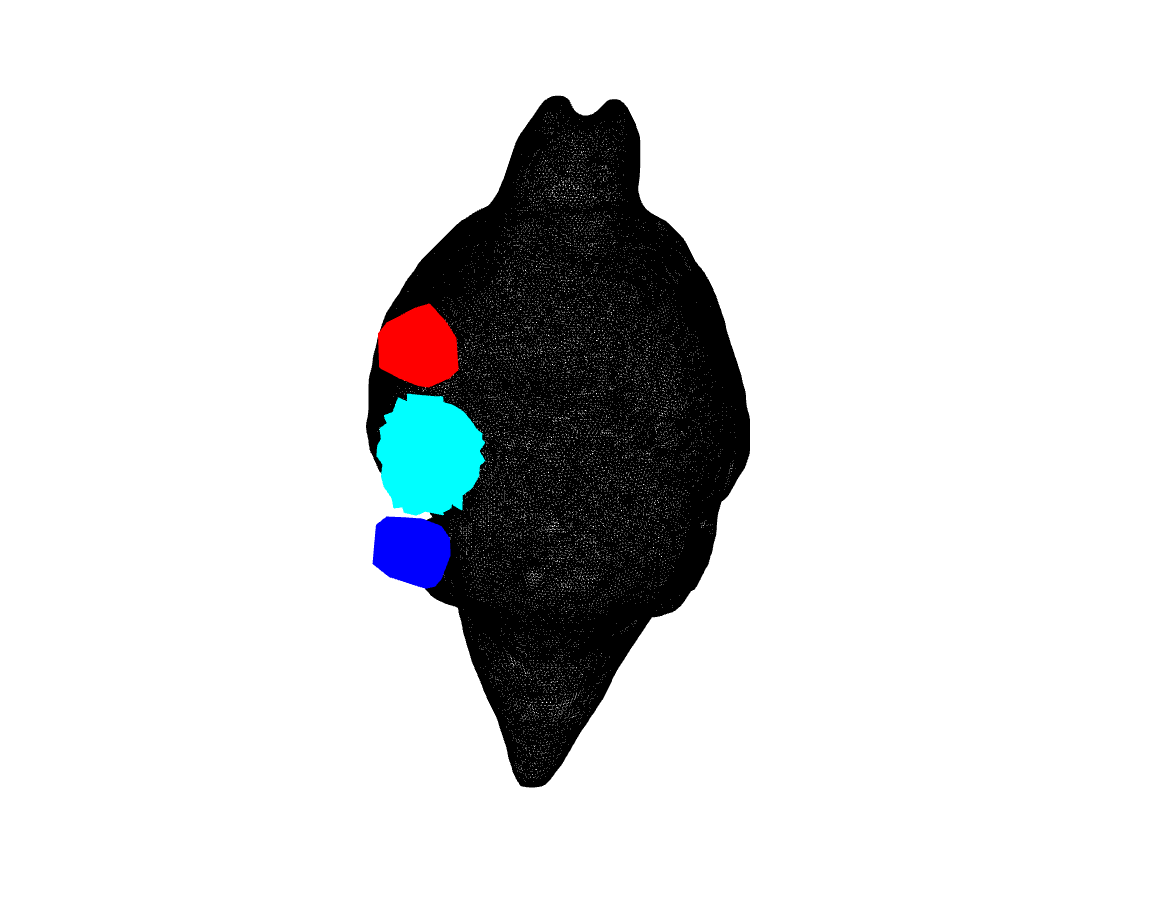

Stage MESH complete - 40.5267 seconds 


o.run(targetStage=Stage.MESH,show=true)

This mesh shows the electrodes in red (anode) and blue (cathode). For the craniotomy, the two tissue types that have been removed (skin and bone) are shown in cyan and magenta. 

### Stage EXPORT: export the mesh and model

Up until this stage, all changes were internal to the Matlab object (saved in *1x1_cran.mat*), now we export files that the FEM solver getDP can read. The *.msh* file contains information on the mesh (all the nodes, elements, labels and boundaries), and the *.pro* file tells getDP which partial differential equations (PDE) model it needs to solve in this mesh.

o.run(targetStage=Stage.EXPORT)

Compute stage EXPORT
----Starting saveMesh...30-May-2025 00:30:47
----saveMesh elapsed time: 53.0826 seconds

----Starting savePro...30-May-2025 00:31:40
----savePro elapsed time: 0.1577 seconds

Stage EXPORT complete - 36.1042 seconds 


For troubleshooting, have a look at the *.pro* file in the project folder; it contains all the model specifications, including conductivity (in siemens per meter S/m) for the different tissues/elements.

type(file(o,"PRO"))

/* 
 .pro file created by EFMouse on 30-May-2025 00:31:40 
 ID: 1x1_cran_csf_csf 
 Dir: /Users/rubensanchez/desktop/efmouse_sim/1x1_cran_csf_csf 
 */

Group {

gray = Region[1];
csf = Region[2];
bone = Region[3];
skin = Region[4];
eye = Region[5];
Anterior = Region[6];
Posterior = Region[7];
leftskin = Region[8];
leftbone = Region[9];
boundaryAnterior = Region[10];
boundaryPosterior = Region[11];
DomainC = Region[{gray,csf,bone,skin,eye,Anterior,Posterior,leftskin,leftbone}];
AllDomain = Region[{gray,csf,bone,skin,eye,Anterior,Posterior,leftskin,leftbone,boundaryAnterior,boundaryPosterior}];
}

Function {

sigma[gray] = 0.275;
sigma[csf] = 1.654;
sigma[bone] = 0.01;
sigma[skin] = 0.465;
sigma[eye] = 0.5;
sigma[Anterior] = 0.3;
sigma[Posterior] = 0.3;
sigma[leftskin] = 1.654;
sigma[leftbone] = 1.654;
du_dnAnterior[] = 69.185272;
du_dnPosterior[] = -85.163364;
}

Jacobian {
  { Name Vol ;
    Case {
      { Region All ; Jacobian Vol ; }
    }
  }
  { Name Sur ;
    Case {
      { Region 

This file can be opened in the getDP gui to run it manually, but Stage.GETDP runs it for you.

### Stage GETDP: run getDP

It will take getDP between 15 and 30 minutes to compute the solutions of the Laplace equation (on 2024 Mac or Windows hardware). The results are saved in *_e.pos* and *_v.pos* files (in getDP format). In the object the results are saved as .field and .voltage.

o.run(targetStage=Stage.GETDP,show=false);

Compute stage GETDP
Info    : Running '/Users/rubensanchez/Desktop/roast/EFmouse_class/EFMouse/lib/getdp-3.2.0/bin/getdpMac /Users/rubensanchez/desktop/efmouse_sim/1x1_cran_csf_csf/1x1_cran_csf_csf.pro -solve EleSta_v -msh /Users/rubensanchez/desktop/efmouse_sim/1x1_cran_csf_csf/1x1_cran_csf_csf.msh -pos Map' [GetDP 3.2.0, 1 node, max. 1 thread]
Info    : Started (Fri May 30 00:32:17 2025, Wall = 0.0740218s, CPU = 0.031532s, Mem = 5.40234Mb)
Info    : Initializing Gmsh
□□Error   : Unknown number option 'General.NativeFileChooser'□
Info    : Loading problem definition '/Users/rubensanchez/desktop/efmouse_sim/1x1_cran_csf_csf/1x1_cran_csf_csf.pro'
Info    : Selected Resolution 'EleSta_v'
Info    : Loading Geometric data '/Users/rubensanchez/desktop/efmouse_sim/1x1_cran_csf_csf/1x1_cran_csf_csf.msh'
Info    : System 'Sys_Ele' : Real
□P r e - P r o c e s s i n g . . .□
Info    : Treatment Formulation 'Electrostatics_v'
  0%    : Pre-processing                              

Use the `plotEf()` function to visualize the electric field in the X direction, and then the electric field magnitude.

----Starting plotEf...30-May-2025 01:08:50


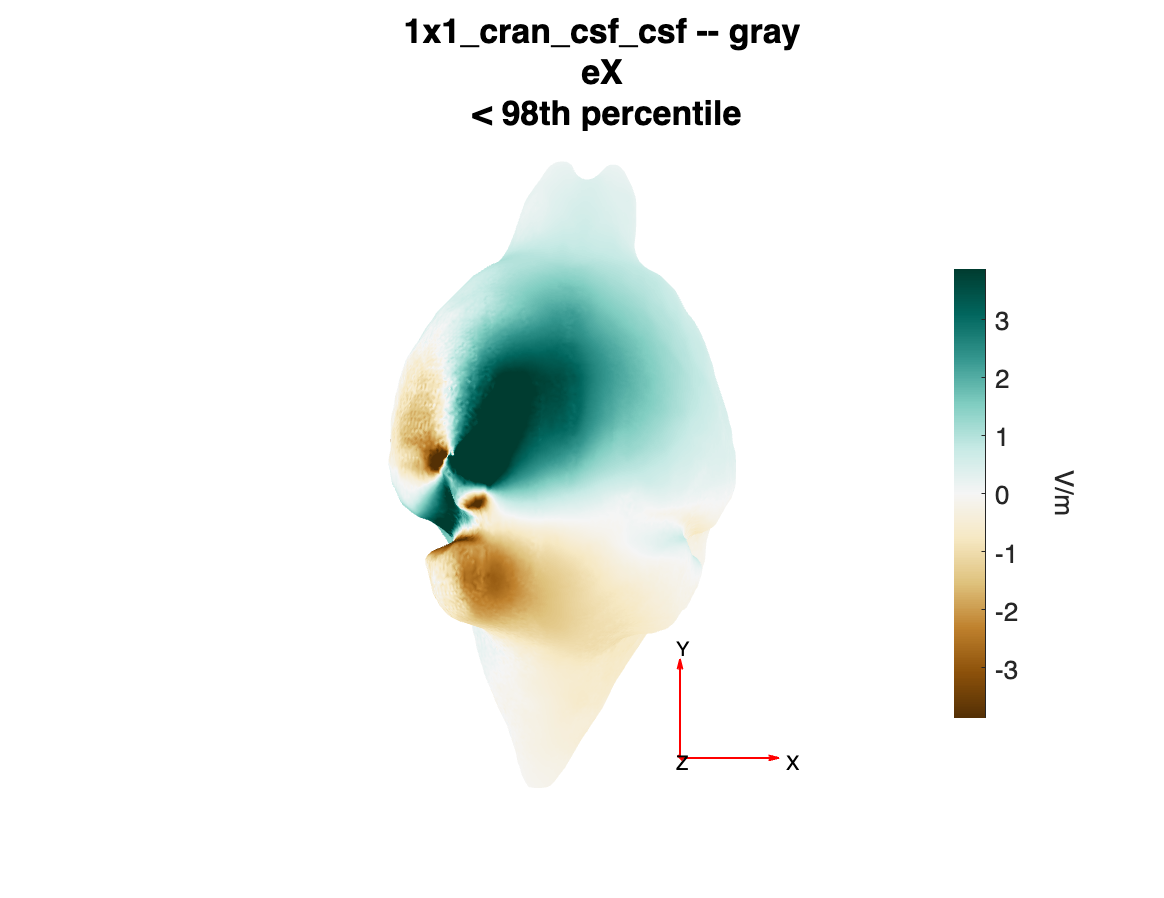

----plotEf elapsed time: 6.6040 seconds


plotEf(o,type='eX',percentile=98, tissue='gray');

----Starting plotEf...30-May-2025 01:08:56


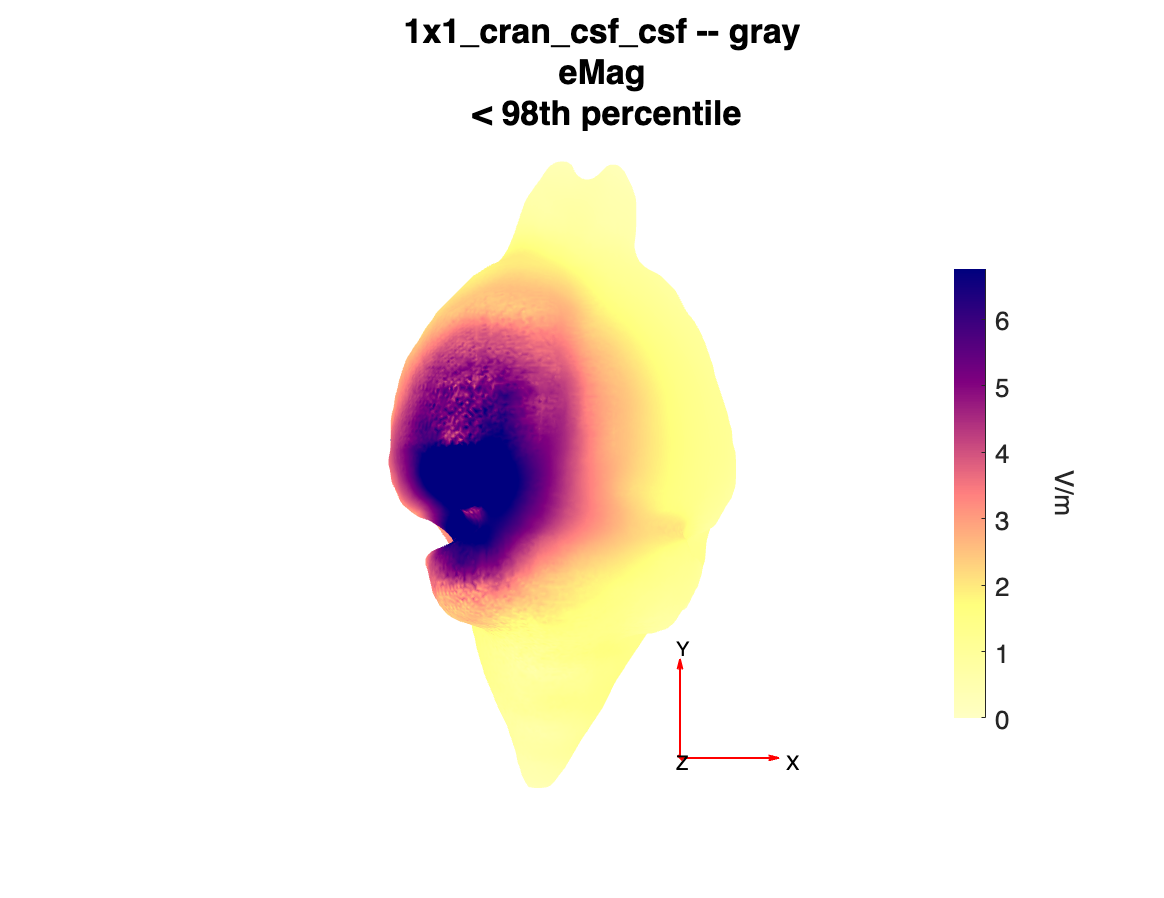

----plotEf elapsed time: 2.6696 seconds


plotEf(o,type='eMag',percentile=98,tissue='gray')

### **Tissue Based Analysis**

In general, we focus on the brain, but if necessary, we can compute electric field estimates for the rest of the mouse body for a full characterization of the anatomical effects of the electrical stimulation protocol. In creating the craniotomy, it was labeled after the tag chosen for the craniotomy and the name of the tissue that was removed. So `leftbone ` is the part of the mouse that was removed from the bone to create the craniotomy.

See Sanchez-Romero et al., (2024) for a full description of the electric field metrics.

analyzeTissue(o,["skin" "gray" "leftbone"])

----Starting analyzeTissue...30-May-2025 01:09:04
Electric field summary statistics for skin tissue
              mean        median        std         min         max  
            ________    ___________    ______    __________    ______

    eX       0.05453    -0.00012349    2.6469       -143.03    114.36
    eY      -0.32071     -1.539e-05    2.9836       -202.54    114.48
    eZ      -0.10273     0.00043175    4.9004       -233.64    225.53
    eMag     0.93864       0.022145    6.2576    1.5219e-07    272.12

[Homogeneity ranges from 0 to 1]
Homogeneity = 0.3751, for ef_norm_mean: (-0.240 -0.079 0.278)

Electric field summary statistics for gray tissue
              mean       median      std   

### ROI Analysis

Now that we have the field estimates for each node in the mesh, we can do an ROI based analysis. For instance, a box ROI.

For the relative focality the reference area is the rest of the gray tissue.

See Sanchez-Romero et al.(2014), for definitions of relative focality and homogeneity. 

roi.shape = 'box';
roi.center = [-3.5,27.5 3.5];
roi.width = 2;  %Left/right
roi.length = 2; % Anterior/Posterior
roi.thickness =1;  % Z
summary = analyzeRoi(o,roi,plot=true,foc_percentile_max=99.9,foc_threshold=75); % Define values for relative focality metric.

----Starting analyzeRoi...30-May-2025 01:09:12
Electric field summary statistics for a box roi in gray
             mean      median      std        min        max  
            _______    _______    ______    _______    _______

    eX       1.1825     1.2358    1.0992    -1.8348     4.4698
    eY      -4.3014    -4.1723     1.113    -8.3354    -1.7983
    eZ      -1.7785    -1.5527    1.4243    -7.7185     2.0486
    eMag     5.1021     4.9182    1.2273     2.8349     10.049

[Relative focality ranges from 0 to 1]
Relative focality = 0.9865, with 160508 reference nodes (cutoff: eMag > 75.00% of the target area max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.9451, for ef_norm_mean: (0.240 -0.844 -0.351)


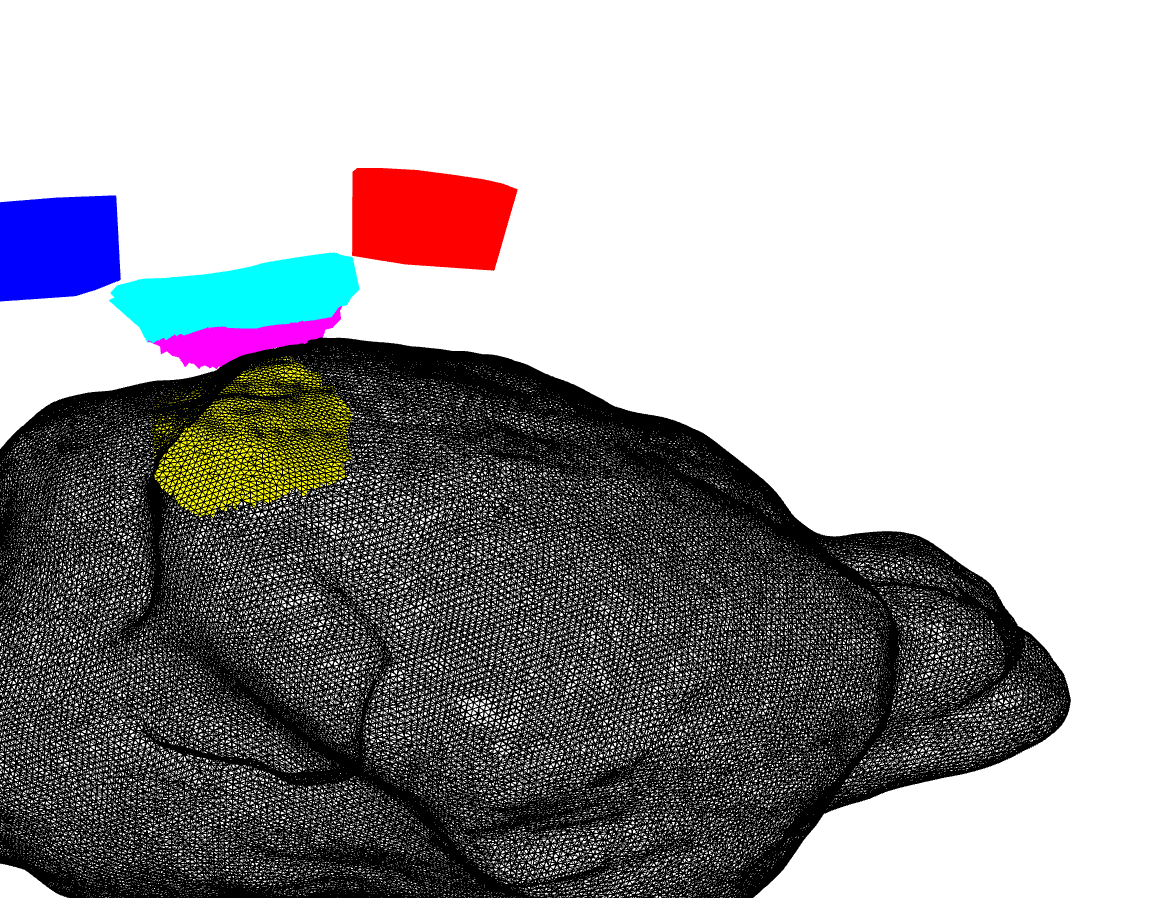

% Rotate and zoom to view the (yellow) box ROI underneath the craniotomy
xlim([-3.31 1.13])
ylim([26.3 36.1])
zlim([2.31 4.98])
view([62.61 27.62])

For comparison, define an analogous box ROI but in the right hemisphere

roiRight = roi;
roiRight.center(1)  =-1* roi.center(1)

roiRight = struct with fields:
        shape: 'box'
       center: [3.5000 27.5000 3.5000]
        width: 2
       length: 2
    thickness: 1


summary = analyzeRoi(o,roiRight,plot=true,foc_percentile_max=99.9,foc_threshold=75);

----Starting analyzeRoi...30-May-2025 01:09:20
Electric field summary statistics for a box roi in gray
              mean       median       std         min         max   
            ________    ________    ________    ________    ________

    eX       0.29218     0.31733     0.26026    -0.55805      0.9135
    eY       -1.3446     -1.3176     0.22369     -2.0414    -0.86765
    eZ      -0.15041    -0.16567    0.086943    -0.35584     0.13753
    eMag      1.4112      1.3943     0.22269     0.91501      2.0499

[Relative focality ranges from 0 to 1]
Relative focality = 0.4469, with 160925 reference nodes (cutoff: eMag > 75.00% of the target area max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.9805, for ef_norm_mean: (0.204 

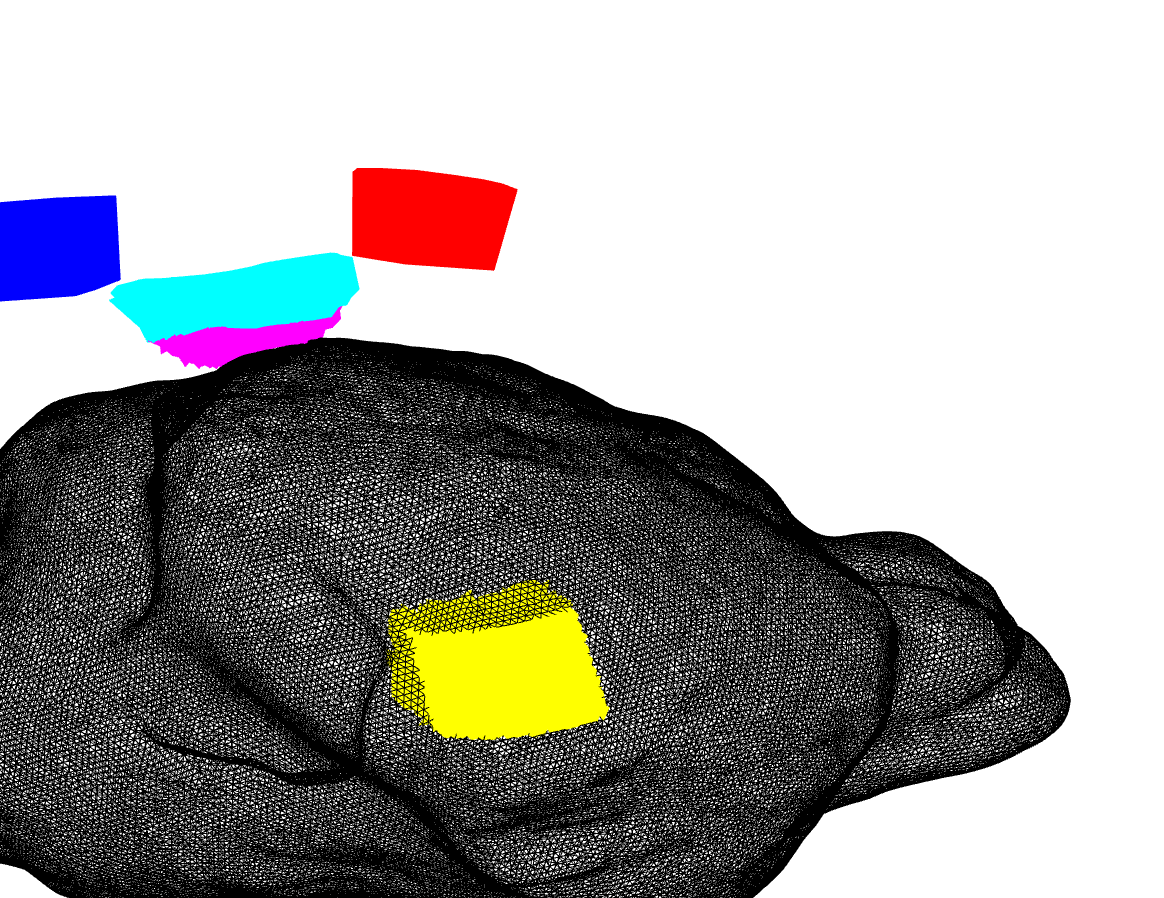

% Rotate and zoom to view the (yellow) box ROI in the right hemisphere
xlim([-3.31 1.13])
ylim([26.3 36.1])
zlim([2.31 4.98])
view([62.61 27.62])

### Stage ATLAS: Volumetric/Atlas Analysis

The mesh coordinates are not particularly intuitive, and you may want to estimate electric fields in specific brain areas (as defined in an atlas). EFMouse does this in reference to the Allen Mouse Brain Atlas. 

To use this, we first have to map the mesh-based results to the Allen Atlas. This is Stage ATLAS of the pipeline. This stage first exports the mesh-based results to a volume (using linear interpolation) and then uses the FLIRT tool in FSL to transform this volume to the coordinates of the Allen Atlas. Note that the alignment between the Digimouse mesh and the Allen Atlas is not perfect because they are based on different imaging modalities (and different mouse strains). (See Sanchez-Romero et al., (2014), for more details.) 

This will fail if FSL is not installed.

o.run(targetStage=Stage.ATLAS,startStage=Stage.ATLAS)

Compute stage ATLAS
----Starting computeVoxelSpace...30-May-2025 01:09:29
----Exporting to NIFTI volumes 
---/Users/rubensanchez/desktop/efmouse_sim/1x1_cran_csf_csf/1x1_cran_csf_csf_efm.nii.gz created
---/Users/rubensanchez/desktop/efmouse_sim/1x1_cran_csf_csf/1x1_cran_csf_csf_efX.nii.gz created
---/Users/rubensanchez/desktop/efmouse_sim/1x1_cran_csf_csf/1x1_cran_csf_csf_efY.nii.gz created
---/Users/rubensanchez/desktop/efmouse_sim/1x1_cran_csf_csf/1x1_cran_csf_csf_efZ.nii.gz created
----computeVoxelSpace elapsed time: 28.7049 seconds
Stage ATLAS complete - 52.4386 seconds 


### Atlas Based Analysis

Once stage 5 has completed we can query electric fields based on a region that is defined in the Allen Atlas. For instance: 'Visual areas' for the left hemisphere.

For the relative focality the reference area is the rest of the Allen atlas "Isocortex".

T = analyzeAtlas(o,"Visual areas",hemisphere="left",foc_threshold=75,foc_percentile_max=99.9,foc_reference='Isocortex');

----Starting analyzeAtlas...30-May-2025 01:10:22
Area: Visual areas (1.0% of brain) , hemisphere left 
             mean      median      std         min        max  
            _______    _______    ______    _________    ______

    eX       2.0453     1.6364    2.5583      -4.0623    13.259
    eY       -6.496    -6.1716    3.0458      -19.208    2.1267
    eZ      -1.4094    -1.0461    3.1113      -16.888    8.0297
    eMag     7.8739     7.1915    3.4893    0.0041008    20.831

[Relative focality ranges from 0 to 1]
Relative focality = 0.9997, with 92410 reference voxels (cutoff: eMag > 75.00% of the target area max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.8894, for ef_norm_mean: (0.256 -0.838 -0.152)
----analyzeAtla

For comparison, we can query results for the right hemisphere, which is contra-lateral from the targeted area.

T = analyzeAtlas(o,"Visual areas",hemisphere="right",foc_threshold=75,foc_percentile_max=99.9,foc_reference='Isocortex');

----Starting analyzeAtlas...30-May-2025 01:10:23
Area: Visual areas (1.0% of brain) , hemisphere right 
              mean       median        std         min        max  
            ________    _________    _______    _________    ______

    eX       0.32005      0.21072    0.35303     -0.56728    1.6958
    eY       -1.6604      -1.8181    0.71333      -2.9166         0
    eZ      0.011844    -0.040232    0.23604     -0.61151    0.7102
    eMag       1.729       1.8691    0.74925    0.0018874    2.9267

[Relative focality ranges from 0 to 1]
Relative focality = 0.5045, with 92457 reference voxels (cutoff: eMag > 75.00% of the target area max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.9784, for ef_norm_mean: (0.178 -0.96

## Tips and Tricks

- The run function can be called with any `targetStage` from Stage.INIT to Stage.ATLAS. Stages that have already been completed will not be run again, and all stages that need to be completed to reach the `targetStage` will be completed in turn.

- IMPORTANT: To continue working with a model from a previous Matlab session, you create an `EFMouse` object with the `dir` and `ID` input arguments to specify the folder with the (previously saved) results and the ID of the montage. For instance, to open the simulation from the tutorial at the stage where it was last saved:

%o = EFMouse(dir='/Users/rubensanchez/desktop/efmouse_sim/1x1_cran_csf_csf',ID='1x1_cran_csf_csf')